# EE525 Project 4

Author: Grant Gallagher

Date: 11/20/2021

Use MATLAB to implement a Kalman filter that tracks a moving target. The dataset is 2D (X,Y) measurement data of the position of a US Navy ship over a span of approximately eight minutes. Set up a Kalman filter with  a  [position_X,  velocity_X,  position_Y,  velocity_Y]  state.  The Kalman filter should function in ‘realtime’ – that is processing should occur as the measurements are read. Experiment with the filter parameters, and study their effects on tracking performance. 

Submit the following:

-  A report documenting the set up and implementation of the filter, plots  of  the  raw  measurements  and  filtered  signal,  the  problems you  encountered,  analysis  and  discussion  of  the  results.  Also include your effort in “tweaking” the filter parameters (55 points).

- Well-documented  source  code.  If  more  than  one  function/file  is  used, provide detailed description as to how to run it (25 points). 

- Repeat 1-2 for an additional dataset. It is a 3D (X,Y,Z) measurement data of the position of a US Navy submarine over a span of approximately two minutes (20 points).  

Clear Console

clc;
clear;

Import the Data

varNames = {'Time','North','East'};
varTypes = {'datetime','double','double'};
ship_data = importShipData('2Ddata.txt',varNames,varTypes)

ship_data = 458×3 table
        Time        North    East 
    ____________    _____    _____

    14:21:19.655    58259    87671
    14:21:20.655    58261    87673
    14:21:21.655    58264    87674
    14:21:22.655    58265    87674
    14:21:23.655    58265    87674
    14:21:24.655    58267    87675
    14:21:25.655    58269    87674
    14:21:26.655    58270    87674
    14:21:27.655    58272    87674
    14:21:28.655    58273    87674
    14:21:29.655    58274    87675
    14:21:30.655    58276    87675
    14:21:31.655    58276    87675
    14:21:32.655    58277    87676
    14:21:33.655    58279    87676
    14:21:34.654    58280    87676


Define State Space Matrix


$$x_{k+1} =x_k +{\dot{x} }_k \Delta t+\frac{1}{2}{\ddot{x} }_k {\Delta t}^2$$



$$\frac{d}{dt}\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack$$



$$\phi_k =e^{F\Delta t} =L^{-1} \left\lbrace {\left(\textrm{sI}-F\right)}^{-1} \right\rbrace$$



$${\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack }_{k+1} =\left\lbrack \begin{array}{cccc}
1 & \Delta t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \Delta t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack }_k +\overrightarrow{w_k }$$


Initial Estimates for ${{\hat{x} }_k }^-$ and its error covariance ${P_k }^-$.

stateVarNames = {'Time','X_North','V_North','X_East','V_East'};
stateVarTypes = {'datetime','double','double','double','double'};
filtered_data = table('Size',[height(ship_data) length(stateVarNames)], ...
                      'VariableTypes',stateVarTypes, ...
                      'VariableNames',stateVarNames);

dt    = 1; % Initial sample time (sec)
x_pos = 60000; % Initial X position (m)
x_vel = 0; % Initial X velocity (m/s)
y_pos = 90000; % Initial Y position (m) 
y_vel = 0; % Initial Y velocity (m/s)
q     = 0.0001; % Process Noise Power
x_hat_prev = [x_pos;
              x_vel;
              y_pos;
              y_vel];
n = length(x_hat_prev); % Order of the system
P_prev = eye(n)*19.2^2;

Define the process and measurement covariance matrices $Q$ and $R$

H = [1 0 0 0;
     0 0 1 0]; % Measurement Matrix
Q = q*[dt^3/3  dt^3/2        0       0;
       dt^3/2      dt        0       0;
       0            0   dt^3/3  dt^2/2;
       0            0   dt^2/2       1];
R = eye(2)*0.1;

Predicted Values

for k = 1:height(ship_data)
    %% --- Measurement Update ("Correct") ---
    % (1) Compute Kalman gain
    K = P_prev*H'*inv(H*P_prev*H'+R)';
    
    % (2) Update estimate with measurement z_k 
    % Store old ship data values
    if k > 1
        time_old = time;
    end
    x_pos_old = x_pos;
    y_pos_old = y_pos;
    
    % Read new ship data values
    [time, x_pos, y_pos] = readShipData(ship_data, k);
    
    % Calculate derivative values
    if k > 1
        dt = datenum(time-time_old)*60*60*24;
        Q = q*[dt^3/3  dt^3/2        0       0;
               dt^3/2      dt        0       0;
               0            0   dt^3/3  dt^2/2;
               0            0   dt^2/2       1];
    end
    x_vel_new = (x_pos-x_pos_old)/dt;
    y_vel_new = (y_pos-y_pos_old)/dt;
    
    x = [x_pos;
         x_vel;
         y_pos;
         y_vel];
     
    z = H*x;
    
    
    x_hat = x_hat_prev+K*(z-H*x_hat_prev);
    % Store filtered data
    filtered_data(k,2:end) = array2table(x_hat');
    filtered_data.Time(k) = time;
    filtered_data.Time.Format = 'HH:mm:ss.SSS';
    
    % (3) Update the error covariance
    P = (eye(n)-K*H)*P_prev;
   
    
    %% --- Time update ("Predict") ---
    % (1) Project the state ahead
    phi = [1 dt 0  0;
           0  1 0  0;
           0  0 1 dt;
           0  0 0  1];
       
    x_hat_new = phi*x_hat;  
    
    x_hat_prev = x_hat_new;
    % (2) Project the error covariance ahead
    P_new = phi*P*phi'+Q;
    P_prev = P_new;
end

Convert Data to table outputs

filtered_data

filtered_data = 458×5 table
        Time        X_North    V_North    X_East    V_East 
    ____________    _______    _______    ______    _______

    14:21:19.655     58259          0     87672           0
    14:21:20.655     58261      1.527     87673      1.3676
    14:21:21.655     58264     2.2637     87674       1.184
    14:21:22.655     58265     1.9581     87674     0.81014
    14:21:23.655     58266     1.5041     87674     0.57278
    14:21:24.655     58267     1.4454     87675     0.56618
    14:21:25.655     58269     1.4845     87675     0.39376
    14:21:26.655     58270     1.4596     87675     0.28771
    14:21:27.655     58272     1.4853     87675     0.21766
    14:21:28.655     58273     1.4704     87675     0.16876
    14:21:29.655     58274     1.4387     87675     0.18292
    14:21:30.655     

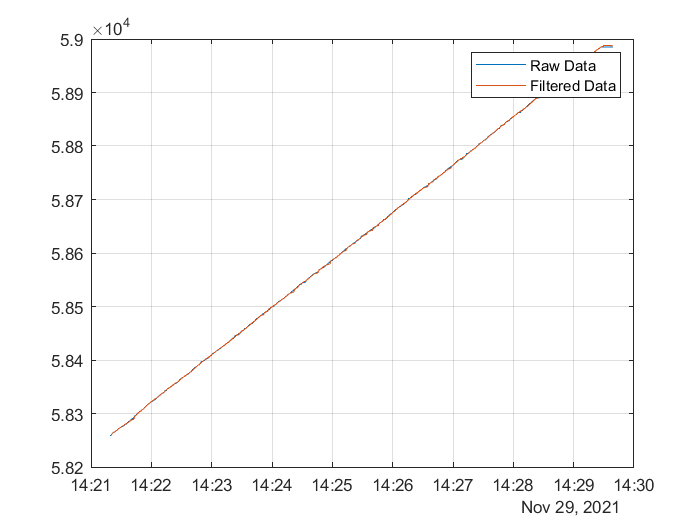

fig2 = figure(2);
hold on
plot(ship_data.Time, ship_data.North)
plot(filtered_data.Time, filtered_data.X_North)
hold off
grid on
box on
legend('Raw Data','Filtered Data')

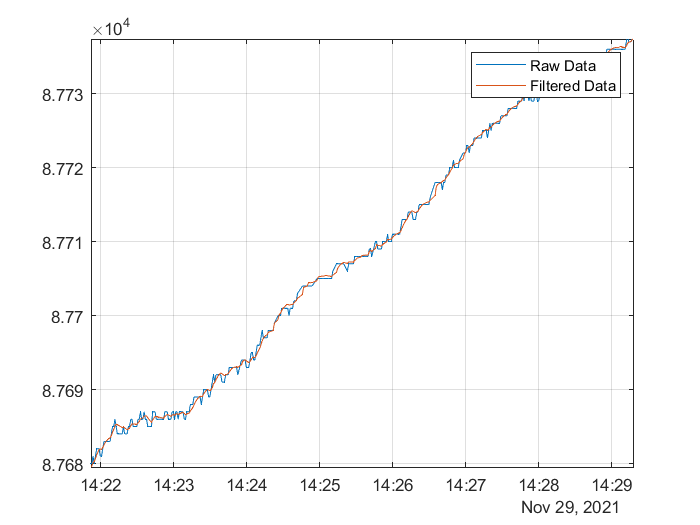


fig3 = figure(3);
hold on
plot(ship_data.Time, ship_data.East)
plot(filtered_data.Time, filtered_data.X_East)
hold off
grid on
box on
legend('Raw Data','Filtered Data')

## Import Data

function dataTable = importShipData(fileName,varNames,varTypes)
    delimiter = '\t';        % Horizontal tab delimiter
    dataStartLine = 8;       % Start on 8th line
    extraColRule = 'ignore'; % Ignore extra columns
    opts = delimitedTextImportOptions('VariableNames',varNames,...
                                    'VariableTypes',varTypes,...
                                    'Delimiter',delimiter,...
                                    'DataLines', dataStartLine,...
                                    'ExtraColumnsRule',extraColRule);
    opts = setvaropts(opts,'Time','InputFormat','HH:mm:ss.SSS'); % Set datetime format
    dataTable = readtable(fileName, opts); % Return the ship data as a table
    dataTable = rmmissing(dataTable,1); % Remove invalid data
    % dataTable.Time = datenum(dataTable.Time); % Convert datetime to serial date number
    
    % Output
    % dataTable.Time = (dataTable.Time - dataTable.Time(1)) * 60 * 60 * 24 + 1; % Convert time to seconds
end

## Read Ship Data

function [time, x_pos, y_pos] = readShipData(ship_data_raw, k)
    time = table2array(ship_data_raw(k,1));
    x_pos = table2array(ship_data_raw(k,2));
    y_pos = table2array(ship_data_raw(k,3));
end

## Van Loan Method

function [phi, Q] = vanLoan(F,G,W,dt)
    % Calculate the size of the system
    n = length(F);
    
    % Determine A and B matrices
    A = [ -F       G*W*G';
          zeros(n)     F']*dt;
    B = expm(A);
    
    % Calculate phi and Q
    phi = B(n+1:end,n+1:end)';
    Q = phi*B(1:n,n+1:end);
end